## Oceanus - Power at Synchronization Bit Calculation

Author: Michel Barbeau, Carleton University

Draft version: March 20, 2021

The power of the signal at the synchronization bits is calculated relative to the cumulative power at the candidate frequency with index $k$.

Over a symbol interval of length $T$, the signal samples $x_t$ correlated with the waveform values $e^{-j 2 \pi f   t} $ are added to obtain the total magnitude at each symbol frequency, $i=0,\dots ,161$, $t=iT+\tau,\ldots,(i+1)T+\tau-1$;$f=-3,-1,1,3$:


$$P_{i,f}  
=
\left\vert 
\sum_{t=iT+\tau}^{(i+1)T+\tau - 1}
x_t \cdot e^{-j 2 \pi f\cdot 0.73  t} 
\right\vert $$


This calculation of cumulative power is represented in the following diagram.

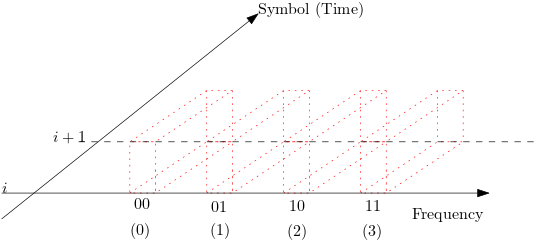

At time index $i$, the frequency offsets $f=-2\ldotp 2,-0\ldotp 73,0\ldotp 73,2\ldotp 2$ correspond to channel symbols 00, 01, 10 and 11, in binary, or 0, 1, 2 and 3, in decimal.  Every box, delimited by red dotted lines, represents a frequency-symbol-amplitude space where sample values for symbol $i$ are correlated with waveform values $e^{-j 2 \pi f\cdot 0.73 \delta t}$ and summed resulting into magnitude denoted as $P_{i,f} $, where $\delta$ represents the sample period (second).  For every channel symbol, note that most significant bit is the data bit while the least significant bit is the synchronization bit.

function P = power_calculation(I, Q, candidate, lag, spsymbol)
    % Inputs
    %   I = In-phase of channel data (baseband)
    %   Q = Quadrature of channel data (baseband)
    %   candidate = Candidate frequency (an index in the -256..0..255
    %   range, every unit represents 0.73 Hz, index 0 is 0 Hz, no drift assumed)
    %   lag = Lag associated with candidate frequency (in samples)
    %   spsymbol = Samples per symbol
    % Output
    %   P = array of powers at synchronization bits
    % create an array of array of powers, 
    P = zeros(162,4); % for every channel symbol (162) and symbol frequency (4)
    delta = 1/375; % sample period (in fraction of second)
    % frequency offsets for symbols 00, 01, 10 an 11 (in Hertz)
    freqs = [-2.2 -0.73 0.73 2.2];
    g = candidate*0.73; % signal index to frequency in Hz
    for i=1:162 % channel symbol loop
        for f=1:4 % symbol frequency loop
            for j=1:spsymbol  % symbol sample loop
                t = (i-1)*spsymbol + lag + j; % time instant (in samples)
                % frequency "g" is in units of 0.73 Hertz
                % multiply baseband signal (rotates clock wise) by its
                % conjugate (rotates counter clock wise), this  ensures that the
               %  product is real and positive definite
                P(i,f) = P(i,f) + complex(I(t),Q(t))*exp(1i*2*pi*(g+freqs(f))*t*delta);
            end
        end
    end
    % compute magnitude
    for i=1:162 % channel symbol loop
        for f=1:4 % symbol frequency loop
            P(i,f) = abs(P(i,f));
        end
    end
end